# Ingenuity

[⇦ Return to the main menu](matlab:open('..\..\MainMenu.mlx'))

The Ingenuity copter is a small autonomous helicopter that made history as the first powered, controlled flight on another planet, Mars. Its design results from a collaboration between the Jet Propulsion Laboratory (JPL) and NASA. This project was part of the Mars 2020 mission and was deployed on Mars by the Perseverance rover. On April 19th, 2021, it was the first helicopter to perform a controlled flight in the thin atmosphere of Mars. Since then, it completed a series of complex flights paving the way for future aerial exploration of other planets.

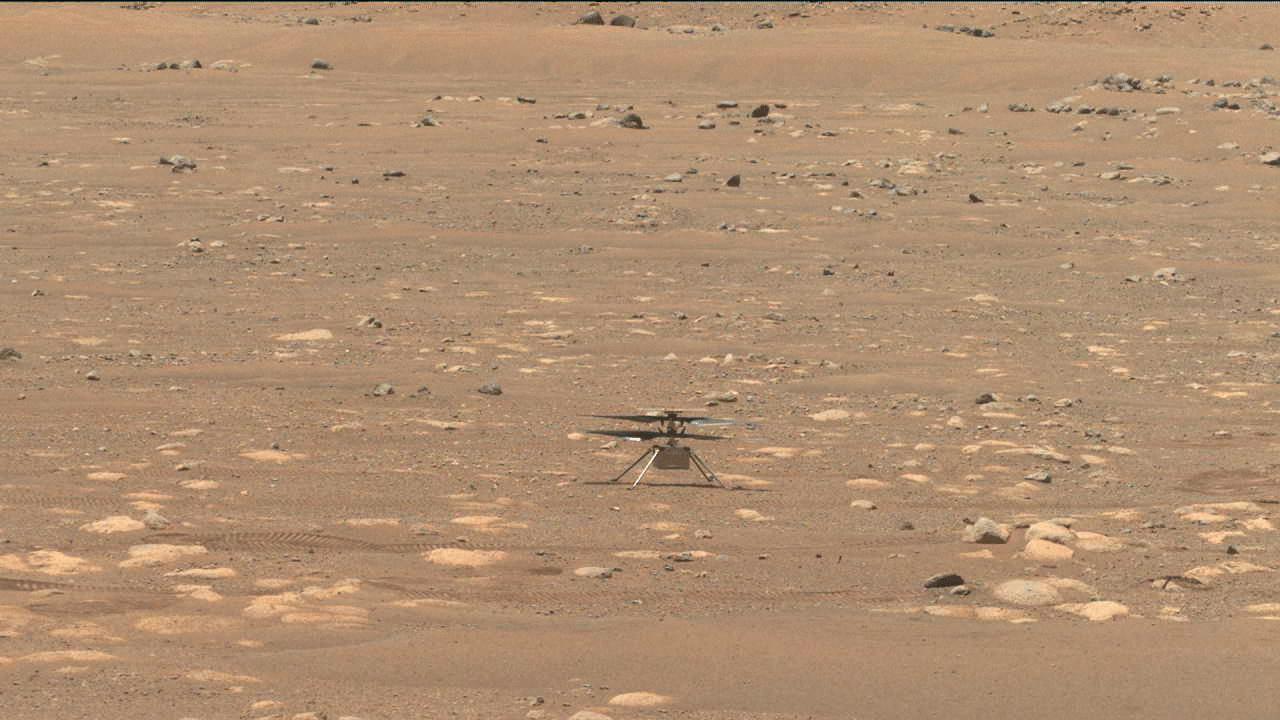

Ingenuity copter blades start to spin, credit: [NASA/JPL-Caltech/ASU](https://www.jpl.nasa.gov/missions/ingenuity)

## **Before you get started**

This live script is intended to be used with the code visible and output inline. On the **View** tab of the MATLAB Toolstrip, in the **View** section, select **Output Inline**. Alternately, select **Output inline** using the icon   at the top right of the Live Editor pane.

 Interacting with this live script will build some familiarity with MATLAB as concepts and commands are introduced together. If you need more instruction, consider taking [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), a free 2-hour online tutorial that teaches the essentials of MATLAB.

   For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one. Some sections depend on variables created in prior sections and will generate errors if run out of order.

The    and   icons refer to two different types of interactive activities that you will find in this script. The    usually indicates an interaction where you will explore the visualization of some concept introduced in this script. 

The  interactions are designed to challenge your understanding of those concepts and may be used for grading and completion checks by your professor.

## Introduction

Dimensional analysis is a powerful mathematical tool that allows engineers to study the consistency of physical equations, derive relationships between physical quantities, and reduce the number of variables involved in a problem. It will enable us to identify parameters that control physical systems and express complex relationships between them using dimensionless numbers. This method is used in engineering, physics, and other sciences to solve problems involving complex physical systems, and it has many practical applications.

### Units and dimensions

 **Definition.** Dimensions are physical quantities that can be measured. Every dimension can be defined based on a combination of fundamental dimensions: mass  $M$, time $T$, length $L$, electric current $I$, temperature $\Theta$, amount of substance $N$ and the luminous intensity $J$. For example, velocity is a physical quantity that can be measured, and its dimension can be expressed as $L\cdot T^{-1}$.

 **Definition.** Units are arbitrary quantities that can be measured and correspond to a precise dimension measurement. For example, one mole is a unit of the amount of substance $N$ used in the International System of Units (SI) that corresponds to $6.022\cdot 10^{23}$ elementary entities (such as atoms or molecules).

  **Try.** Every dimension can be measured using many different units.

 
unitInfo("Length")

While the unit system is often different based on the local tradition and the technical field, in this script, we will use the international system of units for all our measurements and calculation.

  **Try.** Define the base unit system.

 
SIunits = baseUnits('SI')

## Ingenuity's design

### Identify the physical variables

Ingenuity is a small helicopter deployed on planet Mars with the Perseverance rover. It was designed by JPL (Jet Propulsion Laboratory). The helicopter’s wingspan $D$ is 1.2 m, its mass $m$ is 1.6 kg. Mars' atmosphere is defined by its density $\rho$ and viscosity $\mu$, while the acceleration due to the gravitational force is $g$, $\omega$ is the angular velocity of the rotor, and the thrust from the propeller is $F_T$. Note that here $m$ refers to the mass of the helicopter, while $M$ refers to the dimension of mass.

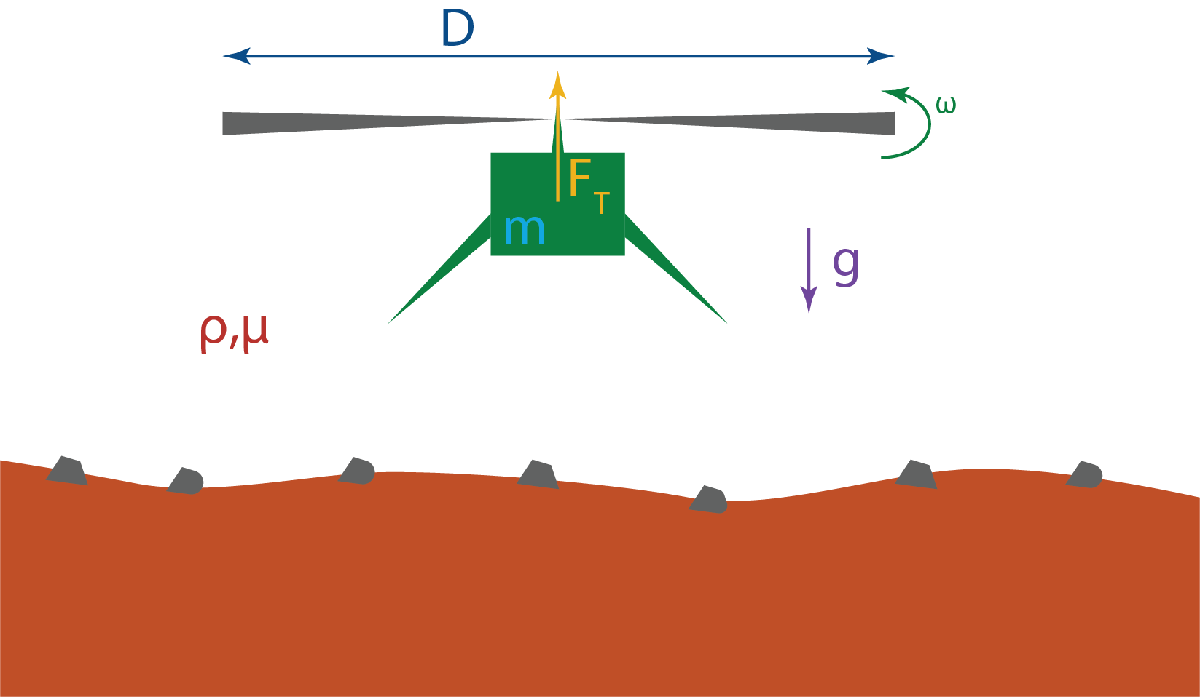

The thrust force of the helicopter can be fitted as a function of all other variables:


$$f(F,\rho,g,\omega,m,D) = 0$$


A naive approach would characterize the helicopter by considering all six parameters  $(\rho,g,\omega,m,D,F)$. This could be done but would require numerous experiments, requiring too much time. Instead, we will perform a dimensional analysis to reduce the number of variables needed to characterize the system.

In the rest of this script, we are going to write each measurement as a value and units such as:


$$\rho = \bar{\rho} \cdot [\text{units}]$$


The first step of the dimensional analysis is to identify the independent parameters and their fundamental dimension. 

  **Try.** Symbolicly define the density as $\rho=\bar\rho\cdot[\text{units of density}]$.

% Define the measurement:
syms rho_bar g_bar omega_bar m_bar D_bar
syms F_bar
% Define the unit system
u = symunit;

rho = rho_bar * (u.kg/u.m^3)
 

 **Exercise.** Modify the following edit fields to add the units to the other parameters.

% Your code goes in the following edit fields:
g = g_bar * (u.m/u.s^2); 
omega = omega_bar * (u.s^-1); 
m = m_bar * (u.kg);
D = D_bar * (u.m);

% Define the lift force:
F = F_bar * u.N;
F = unitConvert(F,SIunits);

  CheckUnitsParameters(g,omega,m,D)

### Determine the number of fundamental dimensions

Each measurement of the parameters is now associated with their units in the SI unit system. 

  **Try.** Modify the following edit field to add the units to the other parameters.

% Gather all the units together in a vector:
unitsUsed = findUnits([rho, g, omega, D, m, F])
 

The Ingenuity design comprises six variables; however, these parameters only use three fundamental dimensions, mass $M$, length $L$ and time $T$. 

### Buckingham**-**$\pi$ **theorem**

 **Definition.** A physical problem involving $n$ variables involving $p$ fundamental dimensions can be expressed as a function of $n-p$ dimensionless quantities.

In the case of the Ingenuity rover we have $n=6$ and $p=3$, therefore the helicopter can be characterized using $n-p=6-3=3$ dimensionless parameters. The Buckingham-$\pi$ theorem gets its name from the Greek letter $\pi$ because the dimensionless numbers are commonly denoted using the letter $\pi$.

The problem:


$$f(F,\rho,g,\omega,m,D) = 0$$


Can be rewritten as:


$$\phi(\pi_1,\pi_2,\pi_3) = 0$$


#### Select repeating variables

We are selecting repeating variables that will appear in $(\pi_1,\pi_2,\pi_3)$. These variables must have units, the units must be different, and their units must cover every dimension:

 **Exercise.** Select the repeating variable.

CheckRepeatingVariable(...
    F,...
    rho,...
    sym("None"));

 

#### Define dimension scale

Many combinations of repeating variables are possible and would lead to the same results. In the rest of the script, we will consider a single set of repeating variables: $[D,\omega,\rho]$. Now that we defined the repeating variables, we can express a characteristic scale for each fundamental dimension involved in the problem.

  **Try.** Click the following button to define the characteristic length scale.

 
L_scale = D

 **Exercise.** Similarly, define the mass and time scales only using the repeating variables.

% Your code goes here"
M_scale = rho*D^3;
T_scale = 1/omega;

% Check answer:
 CheckDimensionScale(M_scale,T_scale)

#### Scale the problem variables

We can now define the dimensionless group as a function of the non-repeating variables $[F,g,m]$ and the characteristic scale of the fundamental dimensions specified in the previous section.

  **Try.** Run the following section to define the dimensional scale for length.

 pi_1 = F / (M_scale*L_scale/T_scale^2)

 **Reflect.** Notice that we can verify that it is a dimensionless number because no units are showing in the results.

 **Exercise.** Reduce the other problem variables to their dimensionless form.

% Your code goes in the following edit fields:
pi_2 = g / (L_scale/T_scale^2)
pi_3 = m / (M_scale)

% Check Answer:
  CheckDiemensionalGroup(pi_2,pi_3)

### Experimental study

A prototype of the Ingenuity copter was tested on Earth. The helicopter mass was fixed to 1.6 $\text{kg}$, five different rotors were tested with radius $R = [1, 3, 10, 30, 100]$ $\text{cm}$. Five different rotor rotation speed were considered $\omega = [1,3,10,30,100]$ $\frac{\text{rad}}{\text{s}}$. The air density of the day of the experiment was 1.2 $\frac{\text{kg}}{\text{m}^3}$ and the local gravitational acceleration is considered equal to 9.81 $\frac{\text{m}}{\text{s}^2}$.

  **Try.** Define the fixed parameters.

rho = 1.2;
g = 9.81;
m = 1.6;

  **Try.** Load the experiment results.

 
load Ingenuity.mat
ExperimentResult

We can now compute the value of the dimensionless group for each experimental result.

  **Try.** Compute $\pi_1$ 

 

ExperimentResult.pi_1 = ExperimentResult.F./...
    ((2*ExperimentResult.R).^4.*ExperimentResult.Omega.^2.*ExperimentResult.Rho)

Recall that the variables you defined were,

displayFormula(["'pi_1 = '" , string(pi_1), "'   and   '","'pi_2 = '", string(pi_2),"'   and   '", "'pi_3 = '", string(pi_3)])

 **Exercise.** Similarly**,** Compute the ratio $\pi_2$ and $\pi_3$ as defined in the previous section.

% Your code goes here:
ExperimentResult.pi_2(:) = g./(2*ExperimentResult.R.*ExperimentResult.Omega.^2);
ExperimentResult.pi_3(:) = m./((2*ExperimentResult.R).^3.*rho);

% Check answer:
  CheckPiExperiment(ExperimentResult)

### Design conclusion

The experimental results demonstrate that the first dimensionless ratio is constant:


$$\pi_1 = \frac{F}{D^4 \omega^2 \rho} = 0.0034$$


The engineering group settles on a rotor diameter of 1.2 $\text{m}$, the atmospheric density on Mars is 0.02 $\frac{\text{kg}}{\text{m}^3}$, the force required for take-off should be 10% greater than the gravitational force felt by the helicopter, the mass of Ingenuity is 1.8 $\text{kg}$ and the local acceleration due to gravity is 3.712 $\frac{\text{m}}{\text{s}^2}$.

  **Try.** Define the minimal rotor rotation speed to operate on Mars.

 

% Define the problem parameters:
syms F D omega rho
pi_1 = F/(D^4*omega^2*rho) == 0.0034
pi_1 = subs(pi_1, [F D rho], [1.1*3.712*1.8 1.2 0.02])
omega = solve(pi_1,omega,"PrincipalValue",true)*u.rad/u.s
omega = rewrite(omega,u.rpm)
omega = vpa(omega,5)

 **Reflect.** Compare the result from our analysis with the [Ingenuity specification](https://mars.nasa.gov/files/mars2020/MarsHelicopterIngenuity_FactSheet.pdf).

## Reynolds number

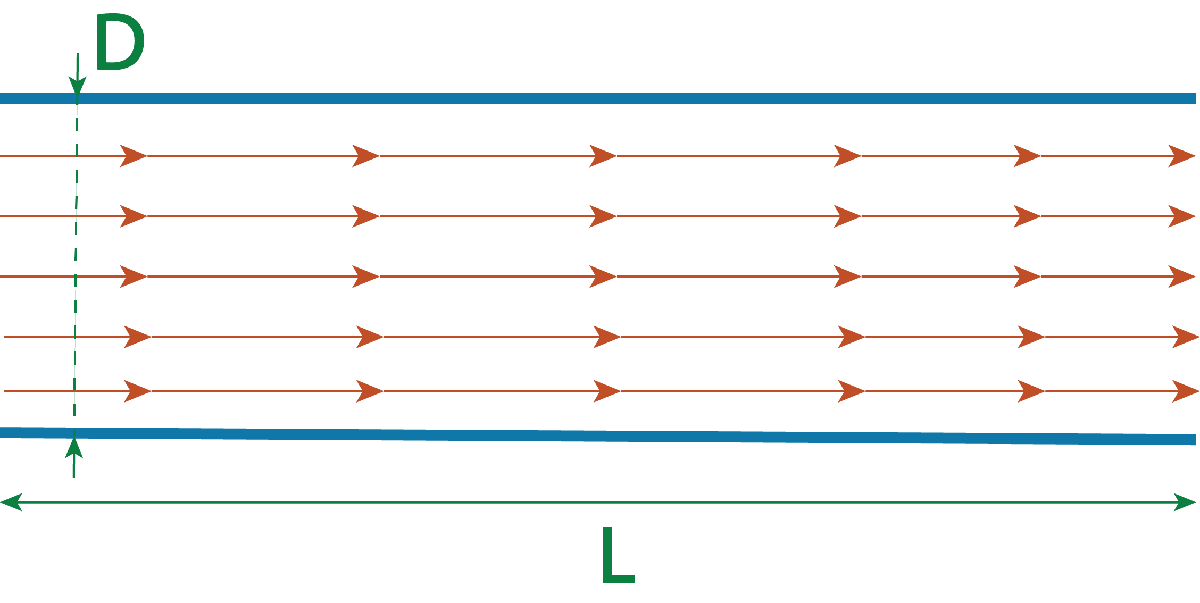

The head loss in the horizontal pipe flow can be expressed as a problem with six variables:


$$f(\Delta P, D, L, \rho,\mu,v) = 0$$


Where $\Delta P$ is the pressure drop, $D$ is the pipe diameter, $L$ is the pipe length, $\rho$ is the fluid density, $\mu$ is the fluid dynamic viscosity and $v$ is the velocity. 

  **Try.** Define the parameter of the problem.

syms D_bar v_bar rho_bar Delta_P_bar mu_bar L_bar
u = symunit;

  **Try.** Define the units of these parameters and check the dimension used.

D = D_bar * u.m;
v = v_bar * u.m/u.s;
rho = rho_bar * u.kg/u.m^3;
Delta_P = Delta_P_bar * u.Pa;
Delta_P = unitConvert(Delta_P,SIunits);
mu = mu_bar * u.kg/u.m/u.s;
L = L_bar * u.m;
unitsUsed = findUnits([D,v,rho,Delta_P,mu,L])

 **Exercise.** Using the Buckingham-Pi theorem, how many dimensionless ratios are needed to characterize the problem?

CheckNumDimRatio(3)
 

The number of variables is $n=6$ and the number of dimensions is $p=3$, therefore we can define $n-p=3$ dimensionless ratio to characterize the problem. 

We select $D
$, $\rho$ and $v$ as repeating variables. The first dimensionless ratio is expressed in term of $L$:

 **Exercise.** Define the first dimensionless ratio based on $L$.

 
% Your code goes here:
pi_1 = L / D

% Check answer:
CheckPi1(pi_1)

 **Exercise.** Define the first dimensionless ratio based on $\Delta P$.

 

% Your code goes here:
pi_2 = Delta_P / (rho*v^2)

% Check answer:
CheckPi2(pi_2)

 **Exercise.** Define the third dimensionless ratio based on $\mu$.

 

% Your code goes here:
pi_3 = mu / (rho*D*v)

% Check answer:
CheckPi3(pi_3)

We can rewrite the problem as:


$$\pi_3 = \phi(\pi_1,\pi_2)$$


The Reynolds number is the most common dimensionless number encountered in fluid mechanics. It is used to predict the fluid flow behavior. It describes if the flow is laminar (low-Reynolds number) or turbulent (high-Reynolds number). It is calculated using the velocity, a length scale, density, and viscosity. You can find more about the Reynolds number in the case of pipe flow in [InternalFlowSoln.mlx](matlab:open('.\InternalFlowSoln.mlx')).

## Other common dimensionless group

Many dimensionless groupings are commonly used depending on the nature of the problem. When the Reynolds number is the most common one that you might encounter, you could find reference to the following dimensionless grouping:

- [Darcy friction factor:](matlab:open('.\InternalFlowSoln.mlx')) $\text{C}_\text{f}$

- Drag coefficient: $c_d = \frac{2F_d}{\rho v^2 A}$

- Euler number: $\text{Eu} = \frac{\Delta p}{\rho V^2}$

- Froude number: $\text{Fr} = \frac{g L^3}{\nu^2}$

- Mach number: $\text{Ma} = \frac{v}{c}$

- Peclet number: $\text{Pe} = \frac{Lu}{D}$

- Pressure coefficient: $C_p = \frac{p-p_\infty}{\frac{1}{2}\rho_\infty V_\infty^2}$

## Further exploration

The experimental data presented in this script were generated using the new [rotor blockset](https://www.mathworks.com/help/releases/R2023a/aeroblks/rotor.html) in Simulink. The block itself uses dimensionless number to simulate the lift generated by a rotor: the lift $(C_L)$ and torque coefficient $(C_Q)$. 

[⇦ Return to the main menu](matlab:open('..\..\MainMenu.mlx'))

## Helper Functions

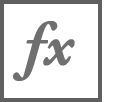`CheckUnitsParameters`

function CheckUnitsParameters(AnswerA,AnswerB,AnswerC,AnswerD)
    arguments
        AnswerA (1,1) sym
        AnswerB (1,1) sym
        AnswerC (1,1) sym
        AnswerD (1,1) sym
    end

    % Define the error flag and the unit system
    ierr = 0;
    u = symunit;

    % check all the units
    if ~checkUnits(AnswerA == u.m/u.s^2,'Consistent')
        if checkUnits(AnswerA == u.m/u.s^2,'Compatible')
            warning("The gravitational acceleration unit is not consistent with the SI"+...
                " units system, try expressing it in meter per second square.")
        else
            warning("The gravitational acceleration unit is not compatible with the"+...
                " dimension of acceleration.")
        end
        ierr = ierr + 1;
    end
    if ~checkUnits(AnswerB == 1/u.s,'Consistent')
        if checkUnits(AnswerB == 1/u.s,'Compatible')
            warning("The rotor angular velocity is not consistent with the SI units system,"+...
                " try expressing it in radian per second.")
        else
            warning("The rotor angular velocity unit is not compatible with the dimension of"+...
                " angular velocity.")
        end
        ierr = ierr + 1;
    end
    if ~checkUnits(AnswerC == u.kg,'Consistent')
        if checkUnits(AnswerC == u.kg,'Compatible')
            warning("The mass is not consistent with the SI units system, try "+...
                "expressing it in kg.")
        else
            warning("The mass unit is not compatible with the dimension of mass.")
        end
        ierr = ierr + 1;
    end
    if ~checkUnits(AnswerD == u.m,'Consistent')
        if checkUnits(AnswerD == u.m,'Compatible')
            warning("The rotor diameter is not consistent with the SI units system, try "+...
                "expressing it in m.")
        else
            warning("The rotor diameter unit is not compatible with the dimension of length.")
        end
        ierr = ierr + 1;
    end

    if ierr == 0
        disp("Good job! All of the units selected are correct.")
    end

end

`CheckRepeatingVariable`

function CheckRepeatingVariable(AnswerA,AnswerB,AnswerC)
    arguments
        AnswerA (1,1) sym
        AnswerB (1,1) sym
        AnswerC (1,1) sym
    end
    sym None
    
    Answers = [AnswerA AnswerB AnswerC];
    [~,combinationUnits] = separateUnits(nchoosek(Answers,2));
    ierr = 0;
    for i = 1:size(combinationUnits,1)
        if isequal(combinationUnits(i,1),combinationUnits(i,2))
            ierr = ierr + 1;
        end
    end
    if ierr ~= 0
        warning("At least two variables present the same dimensions.")
    end
    
    u = symunit;
    unitsUsed = sort(findUnits([AnswerA,AnswerB,AnswerC]));
    unitRequired = sort([u.m u.kg u.s]);
    if isequal(unitsUsed,unitRequired)
        if ierr == 0
            disp("Good job! You defined the repeating variable correctly.")
        end
    else
        warning("Your set of repeating variables does not cover every fundamental"+...
            " dimension involved in this problem.")
    end

end

`CheckDimensionScale`

function CheckDimensionScale(AnswerA,AnswerB)
    arguments
        AnswerA (1,1) sym
        AnswerB (1,1) sym
    end

    syms rho_bar D_bar omega_bar
    u = symunit;
    rho = rho_bar * u.kg/u.m^3;
    D = D_bar * u.m;
    omega = omega_bar / u.s;

    RightAnswerA = rho*D^3;
    RightAnswerB = 1/omega;
    
    if isequal(AnswerA,RightAnswerA) && isequal(AnswerB,RightAnswerB)
        disp("Good job! The dimensional scales are defined correctly")
    else
        warning("At least one of the scales is wrong.")
    end

end

`CheckDiemensionalGroup`

function CheckDiemensionalGroup(AnswerA,AnswerB)
    arguments   
        AnswerA (1,1) sym
        AnswerB (1,1) sym
    end
    
    syms g_bar D_bar omega_bar m_bar rho_bar
    RightAnswerA = g_bar/(D_bar*omega_bar^2);
    RightAnswerB = m_bar/(D_bar^3*rho_bar);

    if isequal(AnswerA,RightAnswerA) && isequal(AnswerB,RightAnswerB)
        disp("Good job! The dimensionless group is defined correctly.")
    else
        warning("At least one of the dimensionless group is wrong.")
    end

end

`CheckPiExperiment`

function CheckPiExperiment(Answer)
    load IngenuitySoln.mat
    
    i2 = all(ExperimentResultSoln.pi_2 == Answer.pi_2);
    i3 = all(ExperimentResultSoln.pi_3 == Answer.pi_3);

    if ~i2
        warning("There is a problem in the calculation for pi_2.")
    end

    if ~i3
        warning("There is a problem in the calculation for pi_3.")
    end

    if i2 && i3
        disp("Good job! You computation of the dimensional groups is correct.")
    end

end


`CheckNumDimRatio`

function CheckNumDimRatio(Answer)
    if Answer == 3
        disp("Good job! You found the right number of dimensionless group.")
    else
        warning("The Buckingham-Pi theorem states that a problem with n parameters and p dimensions can be reduced to (n-p) dimensionless groups.")
    end
end

`CheckPi1`

function CheckPi1(Answer)
    syms L_bar D_bar
    RightAnswer = L_bar/D_bar;
    if isequal(Answer,RightAnswer)
        disp("Good job! You defined the first dimensionless group correctly.")
    else
        warning("Combine L with the repeating variable (D, rho, v) to obtain a dimensionless group.")
    end
end

`CheckPi2`

function CheckPi2(Answer)
    syms Delta_P_bar rho_bar v_bar
    RightAnswer = Delta_P_bar / (rho_bar*v_bar^2);
    if isequal(Answer,RightAnswer)
        disp("Good job! You defined the second dimensionless group correctly.")
    else
        warning("Combine Delta_P with the repeating variable (D, rho, v) to obtain a dimensionless group.")
    end
end

`CheckPi3`

function CheckPi3(Answer)
    syms mu_bar rho_bar D_bar v_bar
    RightAnswer = mu_bar / (rho_bar*D_bar*v_bar);
    if isequal(Answer,RightAnswer)
        disp("Good job! You defined the third dimensionless group correctly.")
        disp("We recognized the Reynolds number:")
        displayFormula("Re = rho_bar * D_bar * v_bar / mu_bar")
    else
        warning("Combine mu with the repeating variable (D, rho, v) to obtain a dimensionless group.")
    end
end

[⇦ Return to the main menu](matlab:open('..\..\MainMenu.mlx'))

Copyright 2023 The MathWorks™, Inc